# Permutation test

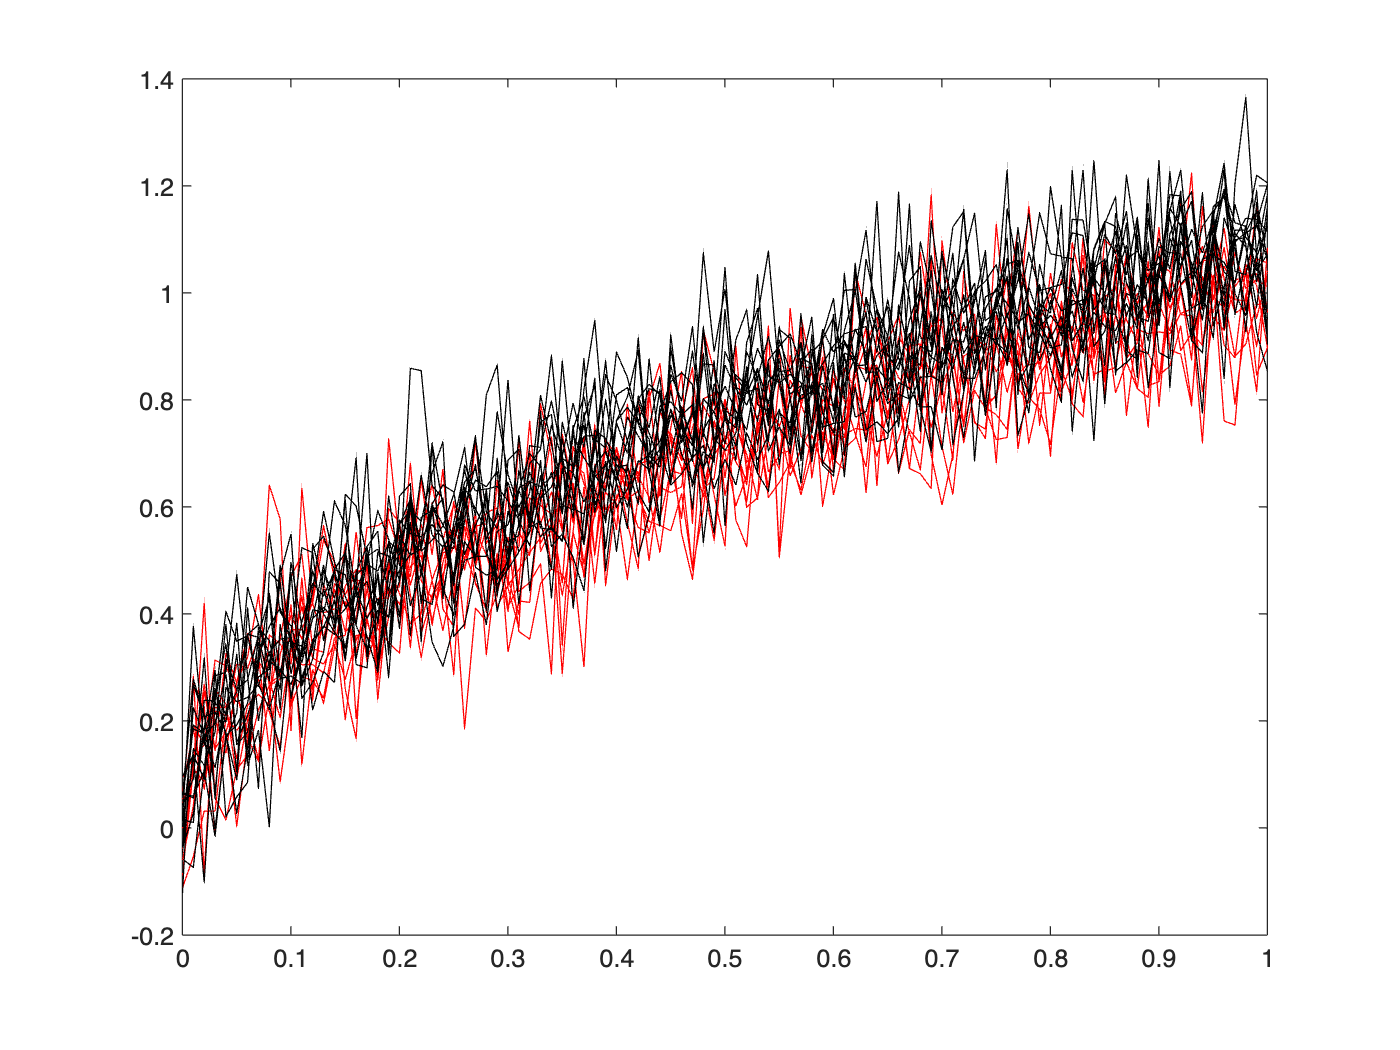

%(C) 2022 Moo K. Chung
% University of Wisconsin-Madison
% 2022, Jan 26; 2026 Feb 12


% We simulate two groups of functional data observed over time t ∈ [0,1].
%
% Group X (n=10) follows mean function       μ_X(t) = sqrt(t)
% Group Y (n=15) follows mean function       μ_Y(t) = sqrt(1.2 t)
% Both groups are corrupted by Gaussian noise with variance 0.1^2.


t=[0:0.01:1];
for i=1:10
    x(i,:)=sqrt(t)+normrnd(0, 0.1,1,length(t));
end

for i=1:15
    y(i,:)=sqrt(1.2*t)+normrnd(0, 0.1,1,length(t));
end

figure; plot(t,x, 'r')
hold on; plot(t,y, '-k')

% Scientific Question: Are the two groups generated from the same underlying mean function?
%
% Null Hypothesis H0:
%   The two groups are exchangeable (no difference in mean functions).
%
% Alternative Hypothesis H1:
%   The two groups have different mean trajectories.


## Data processing - smoothing

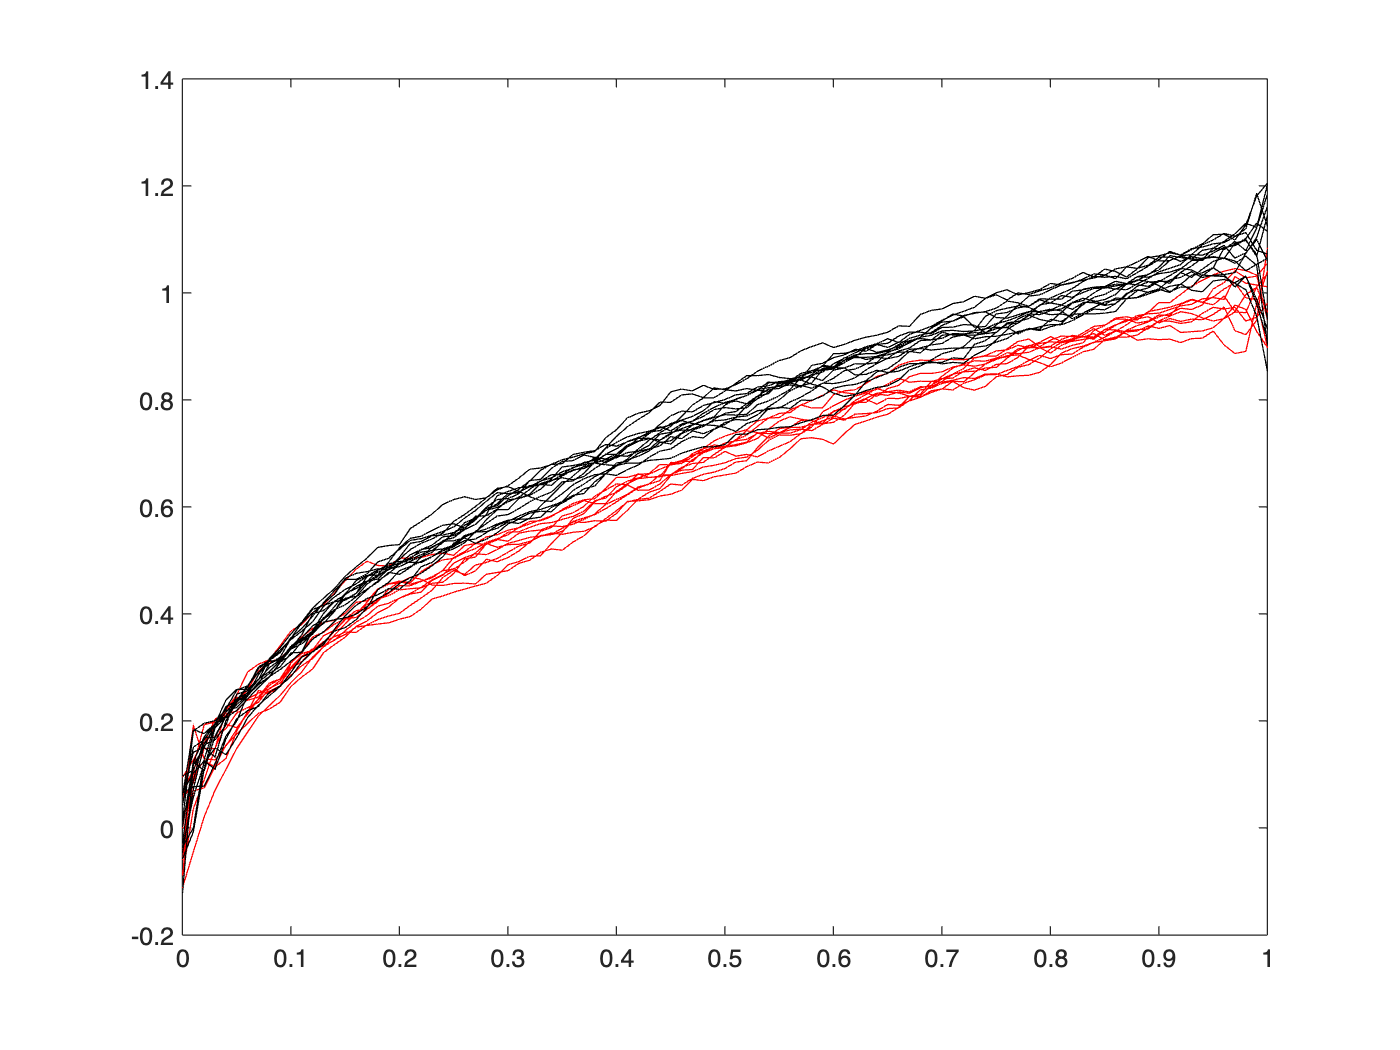

% Functional data are noisy realizations of underlying smooth mean curves.
% Direct comparison of raw trajectories may inflate variance and obscure
% systematic group differences. A common preprocessing step is smoothing.
%

for i=1:10
    x(i,:) = smooth(x(i,:),20); %smooth.m uses the moving average method with window 20
end

for i=1:15
    y(i,:) = smooth(y(i,:),20);
end

figure; plot(t,x, 'r');
hold on; plot(t,y, '-k');

% Smoothing:
%   • reduces within-group variance   --> can you prove?
%   • increases signal-to-noise ratio --> can you prove
%   • improves power of downstream permutation testing  --> can you prove?
%
% Used to be homework problems. 

## Permutation test

% We perform a nonparametric permutation test.
%
% Null Hypothesis H0:
%   The two groups are exchangeable; any labeling into
%   group X (size m) and group Y (size n) is equally likely.
%
% Alternative H1:
%   The two groups differ in their underlying mean functions.
%
% Test Statistic:
%   T = max_t | mean_X(t) - mean_Y(t) |
% This is a Kolmogorov–Smirnov–type supremum distance
% between the two sample mean functions.
% It detects the largest pointwise separation across time
% and controls the family-wise error across the continuum.
%
% The permutation distribution approximates the sampling
% distribution of T under H0 without Gaussian assumptions.

tic
per_s=100000;

m=size(x,1); %sample size in group I
n=size(y,1); %sample size in group II
z=[x; y];  %Combine the data


for i=1:per_s %each iteration gives a permutation
    zper=z(randperm(m+n),:); %random permutation of data z.
    xper=zper(1:m,:);yper=zper(m+1:m+n,:); %permuted data is split into group 1 and 2
    stat_s(i,:)=max(abs(mean(xper)-mean(yper)));
    % test stat = KS-distance 
    %stat_s(i,:)=(mean(x)-mean(y)).*sqrt(m*n*(m+n-2)./((m+n)*((m-1)*var(x)+(n-1)*var(y)))); %t-stat
end

toc

Elapsed time is 0.656171 seconds.



observed_distance = max(abs(mean(x)-mean(y)))

observed_distance = 0.1029

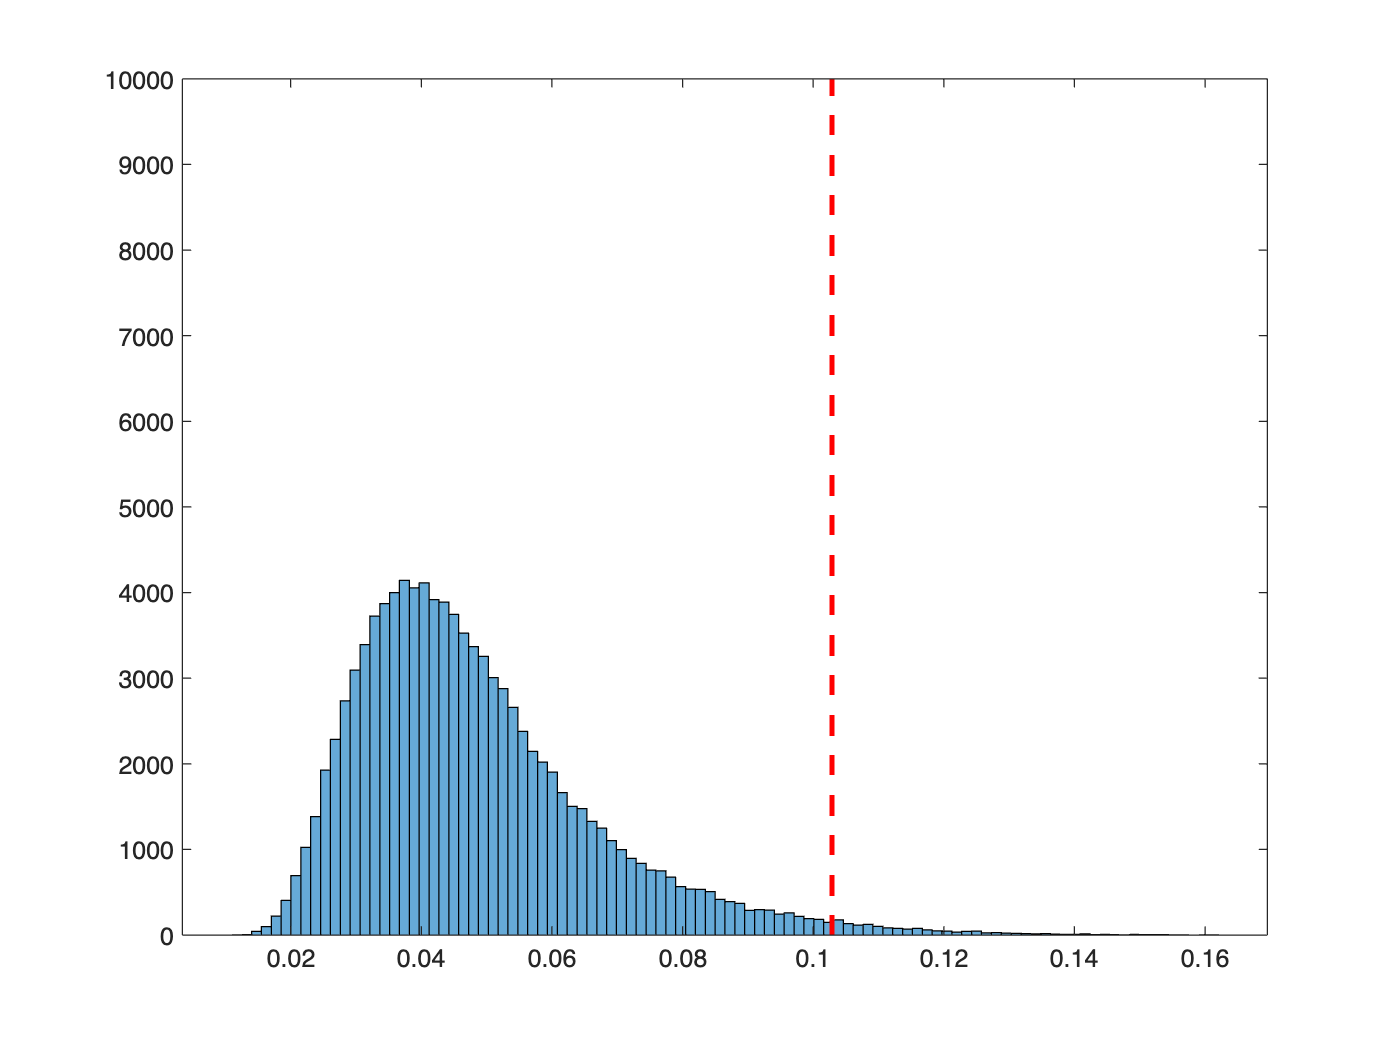


figure; histogram(stat_s,100);
hold on; plot([observed_distance observed_distance],[0 10000],'--r','linewidth',2);


pvalue = online_pvalue(stat_s, observed_distance); %pvalue is computed in an online fashion. 
pvalue=pvalue(end)

pvalue = 0.0147

% Self-assessment problems:
% 1) If you increase the amount of smoothing, you will get a smaller p-value in most cases, 
% increasing discrimination power. Check this claim. 
% 2) How you handle missing data in the permutation test.


## PROJECT 17:  Topologically Invariant Permutations

% Goal: To design and implement permutation tests whose test statistics 
% are topologically invariant. Students will work with permuting entries of 
% incidence matrices (graphs) or boundary matrices (simplicial complexes)
% that will results in topologicall invariant test statistic. 
%
% Description: Students are given two boundary matrices Bk that 
% represent two objects (simplicial complexes). A naive entry-wise shuffle 
% destroys feasibility (the matrix no longer encodes a valid boundary operator 
% and breaks the chain property B_{k-1}*B_k = 0). Arbitrary entry-wise 
% shuffling does not preserve topology. The key idea is that topology is 
% preserved only under relabeling of simplices, implemented by permuting 
% rows and columns of the boundary matrix using permutation matrices. 
% The permutation test is then built by repeatedly generating randomized 
% pairs (B^{(1)}_perm, B^{(2)}_perm) via such relabelings, computing a 
% topologically invariant distance (or statistic) between them, and 
% comparing the observed value to the null distribution. The null model 
% tests whether the two inputs are distinguishable beyond relabeling. 
% Students will then extend the idea to two groups of boundary matrices.
%
% Learning outcomes: Students will understand how incidence and 
% boundary matrices encode intrinsic topology and why structured 
% relabelings preserve that topology. They will learn that algebraic 
% invariants such as rank, nullity, Betti numbers, and Laplacian 
% spectra are unchanged under permutation similarity.Students will design 
% coordinate-free test statistics and implement permutation-based 
% inference that respects topological structure.


